### 函数


$$f(x,y)=20\times(x^2-y^2)^2-(1-y)^2-3\times(1+y)^2+0.3$$


其中 $x\in[-5,5]$ $y\in[-5,5]$

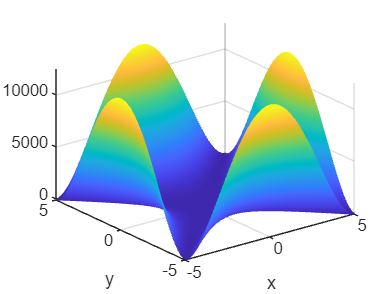

clear;
close all;
clc;
x = -5:0.01:5;
y = -5:0.01:5;
N= size(x,2);

for i = 1:N
    for j = 1:N
        z(i,j) = 20*(x(i)^2-y(j)^2)^2-(1-y(j))^2 ...
        -3*(1+y(j))^2+0.3;
    end
end

mesh(x,y,z);
xlabel('x');
ylabel('y');

clc;
clear;
close all;

m = 20;%蚂蚁数量
G = 200;%最大迭代次数
Rho = 0.9;%信息素蒸发系数
P0 = 0.2; %转移概率常数
step=0.1;%搜索步长

XMAX = 5;
XMIN = -5;
YMAX = 5;
YMIN = -5;

## 随机设置蚂蚁初始位置

Tau 信息素初始矩阵

for i=1:m
    X(i,1)=(XMIN+(XMAX-XMIN)*rand);%x值
    X(i,2)=(YMIN+(YMAX-YMIN)*rand);%y值
    Tau(i)= func(X(i,1),X(i,2)); %循环计算每一对x和y的适应度d
end

function value = func(x,y)
value = 20*(x^2-y^2)^2-(1-y)^2 -3*(1+y)^2+0.3;
end

for NC = 1:G
    lamda = 1/NC;
    [Tau_best,BestIndex] = min(Tau);
    for i = 1:m
        P(NC,i) = (Tau(BestIndex)-Tau(i))/Tau(BestIndex)
    end
    %%% 位置更新%%%
    for i = 1:m
        %%%局部搜索%%%
        if P(NC,i) < P0
            temp1 = X(i,1)+(2*rand -1)*step*lamda;
            temp2 = X(i,2)+(2*rand -1)*step*lamda;
        else
            %%%%全局搜索%%%
            temp1 = X(i,1)+(XMAX-XMIN)*(rand-0.5);
            temp2 = X(i,2)+(YMAX-YMIN)*(rand-0.5);
        end

        %%%边界处理%%%
        if temp1<XMIN
            temp1 = XMIN;
        end

        if temp1>XMAX
            temp1 = XMAX;
        end

        if temp2<XMIN
            temp2 = XMIN;
        end

        if temp2 >XMAX
            temp2 =XMAX;
        end

        %%%判断蚂蚁是否移动%%%
        if func(temp1,temp2) < func(X(i,1),X(i,2))
            X(i,1) = temp1;
            X(i,2) = temp2;
        end
    end
    %%%更新信息素%%%
    for i = 1:m
        Tau(i) = (1-Rho)*Tau(i)+func(X(i,1),X(i,2));
    end

    [value,index] = min(Tau);
    
    trace(NC) = func(X(index,1),X(index,2))
end

脚本中的函数定义必须出现在文件的结尾。
请将 "func" 函数定义后面的所有语句都移到第一个局部函数定义前面。

P = 121.4409

P =   121.4409    4.1405


P =   121.4409    4.1405    4.0582


P =   121.4409    4.1405    4.0582    3.5201


P =   121.4409    4.1405    4.0582    3.5201  100.1179


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695


trace = -15.9022

P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135         0         0         0         0         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0         0         0         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0         0         0         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813         0         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695


trace =   -15.9022 -123.7000


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275         0         0         0         0         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901         0         0         0         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546         0         0         0         0         0         0         0         0         0         0         0


P =   121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320         0         0         0         0         0         0         0         0         0         0


P = 3×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094         0         0         0         0         0         0         0         0         0


P = 3×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413         0         0         0         0         0         0         0         0


P = 3×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604         0         0         0         0         0         0         0


P = 3×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116         0         0         0         0         0         0


P = 3×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735         0         0         0         0         0


P = 3×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302         0         0         0         0


P = 3×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202         0         0         0


P = 3×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0         0


P = 3×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0         0


P = 3×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810


trace = 1×3
  -15.9022 -123.7000 -123.7000


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613         0         0         0         0         0         0         0         0         0         0         0         0         0


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109         0         0         0         0         0         0         0         0         0         0         0         0


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699         0         0         0         0         0         0         0         0         0         0         0


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210         0         0         0         0         0         0         0         0         0         0


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593         0         0         0         0         0         0         0         0         0


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998         0         0         0         0         0         0         0         0


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826         0         0         0         0         0         0         0


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296         0         0         0         0         0         0


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764         0         0         0         0         0


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801         0         0         0         0


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855         0         0         0


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0         0


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0         0


P = 4×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830


trace = 1×4
  -15.9022 -123.7000 -123.7000 -123.7000


P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458         0         0         0         0         0         0         0         0         0         0         0         0         0       

P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991         0         0         0         0         0         0         0         0         0         0         0         0       

P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719         0         0         0         0         0         0         0         0         0         0         0       

P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903         0         0         0         0         0         0         0         0         0         0       

P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713         0         0         0         0         0         0         0         0         0       

P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935         0         0         0         0         0         0         0         0       

P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600         0         0         0         0         0         0         0       

P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784         0         0         0         0         0         0       

P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668         0         0         0         0         0       

P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434         0         0         0         0       

P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148         0         0         0       

P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872         0         0       

P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736         0       

P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 5×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

trace = 1×5
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000


P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 6×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

trace = 1×6
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 7×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

trace = 1×7
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 8×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

trace = 1×8
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

P = 9×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038       

trace = 1×9
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 10×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×10
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 11×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×11
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 12×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×12
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 13×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×13
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 14×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×14
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 15×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×15
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 16×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×16
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 17×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×17
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 18×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×18
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 19×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×19
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 20×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×20
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 21×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×21
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 22×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×22
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 23×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×23
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 24×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×24
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 25×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×25
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 26×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×26
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 27×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×27
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 28×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×28
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 29×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×29
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 30×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×30
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 31×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×31
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 32×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×32
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 33×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×33
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 34×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×34
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 35×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×35
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 36×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×36
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 37×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×37
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 38×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×38
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 39×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×39
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 40×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×40
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 41×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×41
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 42×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×42
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 43×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×43
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 44×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×44
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 45×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×45
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 46×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×46
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 47×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×47
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 48×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×48
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 49×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×49
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 50×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×50
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 51×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×51
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 52×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×52
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 53×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×53
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 54×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×54
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 55×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×55
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 56×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×56
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 57×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×57
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 58×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×58
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 59×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×59
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 60×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×60
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 61×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×61
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 62×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×62
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 63×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×63
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 64×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×64
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 65×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×65
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 66×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×66
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 67×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×67
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 68×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×68
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 69×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×69
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 70×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×70
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 71×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×71
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 72×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×72
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 73×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×73
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 74×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×74
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 75×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×75
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 76×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×76
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 77×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×77
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 78×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×78
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 79×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×79
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 80×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×80
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 81×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×81
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 82×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×82
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 83×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×83
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 84×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×84
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 85×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×85
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 86×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×86
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 87×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×87
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 88×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×88
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 89×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×89
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 90×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×90
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 91×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×91
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 92×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×92
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 93×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×93
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 94×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×94
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 95×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

trace = 1×95
  -15.9022 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000 -123.7000


P = 96×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 96×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      

P = 96×20
  121.4409    4.1405    4.0582    3.5201  100.1179  265.7849  435.1135   59.4380         0   18.9883   36.8238  205.6217   51.7234   38.9018   13.4504  329.6791   11.2261    2.8620   93.3479    0.8695
   28.9602    4.1405    4.0582    3.5201   20.9615  232.0798  435.1135   13.3372         0    4.5813   36.8238   19.4330   13.1433   38.9018    6.9083   36.2781    0.7106    2.8620    2.3236    0.8695
    3.8543    1.4567    1.4447    1.3665    2.8657   34.1614   64.1275    2.1901    0.8546    1.3320    6.2094    1.2413    2.2604    6.5116    1.7735    2.1302    0.8202    1.2708         0    0.9810
    3.4456    1.4085    1.3978    1.3278    0.5505   14.4426   57.4613    2.0109    0.8699    1.0210    5.6593    0.9998    2.0826    5.9296    1.0764    1.0801    0.6855    1.2422         0    0.9830
    3.4095    1.4042    0.6372    1.3243    0.3458   12.6991   56.8719    0.4903    0.8713    0.9935    0.5600    0.9784    2.0668    3.7434    1.0148    0.9872    0.6736    1.0038      


[min_value,min_index] = min(Tau);
minX = X(min_index,1);
minY = X(min_index,2);
minValue = func(X(min_index,1),X(min_index,2));


figure
plot(trace);
xlabel('搜索次数');
ylabel('适应度值');
title('适应度进化曲线');
